# 01A. Basics of programming in MATLAB

## Mingyang Lu

## 01/06/2024

## Get help in MATLAB

Use help to get help for a specific command or function.  

help rand

 rand Uniformly distributed pseudorandom numbers.
    R = rand(N) returns an N-by-N matrix containing pseudorandom values drawn
    from the standard uniform distribution on the open interval(0,1).  rand(M,N)
    or rand([M,N]) returns an M-by-N matrix.  rand(M,N,P,...) or
    rand([M,N,P,...]) returns an M-by-N-by-P-by-... array.  rand returns a
    scalar.  rand(SIZE(A)) returns an array the same size as A.
 
    Note: The size inputs M, N, P, ... should be nonnegative integers.
    Negative integers are treated as 0.
 
    R = rand(..., CLASSNAME) returns an array of uniform values of the 
    specified class. CLASSNAME can be 'double' or 'single'.
 
    R = rand(..., 'like', Y) is an array of uniform values with the same
    data type and complexity (real or complex) as the numeric variable Y.
 
    The sequence of


% use doc to get document for a specific topic
% doc random

## Typical data types & math operations

% integer, real number; assignment to a
a = 10 + 3.14;

% a multiplies a
result_square = a * a;

% square of a, which gives the same value as the previous one
result_power = a^2;

% complex number; assignment to b
b = complex(3.0, 4.0);

% The modulus of b
result_modulus = abs(b);

% logical; c is TRUE
c = 3 + 4 == 7;

% not c, which is FALSE
result_logical = ~c;

% character
d = 'Monday';

% show the data type of d
result_type = class(d);

% number of characters in a string
result_length = numel(d);

% Display the results
disp(result_square);

  172.6596



disp(result_power);

  172.6596



disp(result_modulus);

     5



disp(result_logical);

   0



disp(result_type);

char


disp(result_length);

     6



## Vectors

% a cell array of characters
vec = {'Man', 'Woman', 'Woman', 'Man', 'Woman'};

% length of the cell array
length_of_vec = numel(vec);
fprintf('Length of vec: %d\n', length_of_vec);

Length of vec: 5



% logical values, compare each element to 'Woman'
logical_values = strcmp(vec, 'Woman');
disp('Logical values:');

Logical values:


disp(logical_values);

   0   1   1   0   1




% identify the indices of the elements being 'Woman'
indices_of_woman = find(strcmp(vec, 'Woman'));
fprintf('Indices of ''Woman'': %s\n', mat2str(indices_of_woman));

Indices of 'Woman': [2 3 5]


## Categorical data

% a cell array of characters
vec = {'Man', 'Woman', 'Woman', 'Man', 'Woman'};

% convert the cell array to a table with a categorical variable
vec_cat = categorical(vec);

% check the data types
fprintf('Type of vec: %s\n', class(vec));

Type of vec: cell


fprintf('Type of vec_cat: %s\n', class(vec_cat));

Type of vec_cat: categorical



% levels of the categorical variable
levels_of_vec_cat = categories(vec_cat);
fprintf('Levels of vec_cat: %s\n', strjoin(levels_of_vec_cat, ', '));

Levels of vec_cat: Man, Woman



% number of levels
num_levels_of_vec_cat = numel(levels_of_vec_cat);
fprintf('Number of levels of vec_cat: %d\n', num_levels_of_vec_cat);

Number of levels of vec_cat: 2


## If statement

a = 0;

% conditions
if a == 1
    disp('a equals to 1');
else
    disp('a is not 1');
end

a is not 1


## For loops

for i = 1:5
    disp(i);
end

     1

     2

     3

     4

     5



Another way to use for loop

v = [1, 2, 5, 7];

for i = v
    disp(i);
end

     1

     2

     5

     7



## While statement

i = 0;

while i < 5
    i = i + 2;
    disp(i);
end

     2

     4

     6



## Matrix and vector operations

% Generate a random matrix of 4 x 4
mat = randn(4, 4);

% Display the matrix
disp('Matrix:');

Matrix:


disp(mat);

    0.6753   -0.0433    0.2532    0.1069
    0.1514   -0.5837   -0.1774   -1.8595
   -0.8789    1.6456   -0.2591    0.0198
   -0.1916    0.7245    0.6117    0.7927




% Calculate row sums
row_sums = sum(mat, 2);

% Calculate column sums
column_sums = sum(mat, 1);

disp('Row sums:');

Row sums:


disp(row_sums');

    0.9921   -2.4691    0.5275    1.9372




disp('Column sums:');

Column sums:


disp(column_sums);

   -0.2438    1.7430    0.4285   -0.9401



"rowfun" in MATLAB is close to "apply" in R. The function works for a table.

% Create a sample table
data = table(mat);

% Apply row sum using rowfun
result = rowfun(@sum, data, 'OutputFormat', 'uniform');
disp(result);

    0.9921
   -2.4691
    0.5275
    1.9372




% Apply column sum
data2 = table(mat');
result2 = rowfun(@sum, data2, 'OutputFormat', 'uniform');
disp(result2);

   -0.2438
    1.7430
    0.4285
   -0.9401



## Functions

% Function myfunction is defined at the end of the file

% Call the function with an argument
b = myfunction(4);
disp(['b = ', num2str(b)]);

b = 16


## Cell array with different data types

% Define a new cell array
my_cell_array = {'a', [1, 2, 3], false, 3.14};

% The first element
disp(['First element: ', my_cell_array{1}]);

First element: a



% The second element
disp(['Second element: ', mat2str(my_cell_array{2})]);

Second element: [1 2 3]



% Map names to elements using a containers.Map object
my_map = containers.Map({'letters', 'array', 'TF', 'pi'}, my_cell_array);

% Retrieve elements by names
disp(['TF element: ', num2str(my_map('TF'))]);

TF element: 0


## Table

% Define a new table with variables of the same length
id = [1; 2; 3; 4; 5];
atom = {'N'; 'CA'; 'CB'; 'C'; 'O'};
mass = [14; 12; 12; 12; 16];
size = [1.2; 1.4; 1.4; 1.4; 1.1];

my_data = table(id, atom, mass, size);

% Display the table
disp('Table:');

Table:


disp(my_data);

    id     atom     mass    size
    __    ______    ____    ____

    1     {'N' }     14     1.2 
    2     {'CA'}     12     1.4 
    3     {'CB'}     12     1.4 
    4     {'C' }     12     1.4 
    5     {'O' }     16     1.1 




% Get variable names
disp('Variable names:');

Variable names:


disp(my_data.Properties.VariableNames);

    {'id'}    {'atom'}    {'mass'}    {'size'}




% Display variable information
disp('Variable Information:');

Variable Information:


disp(varfun(@class, my_data));

    class_id    class_atom    class_mass    class_size
    ________    __________    __________    __________

     double        cell         double        double  




% Retrieve a variable
disp('Variable ''mass'':');

Variable 'mass':


disp(my_data.mass);

    14
    12
    12
    12
    16




% Add a variable
my_data.backbone = [true; true; false; true; true];

% Display the updated table
disp('Updated Table:');

Updated Table:


disp(my_data);

    id     atom     mass    size    backbone
    __    ______    ____    ____    ________

    1     {'N' }     14     1.2      true   
    2     {'CA'}     12     1.4      true   
    3     {'CB'}     12     1.4      false  
    4     {'C' }     12     1.4      true   
    5     {'O' }     16     1.1      true   




% Add a row
new_row = table(6, {'S'}, 32, 1.6, false, 'VariableNames', my_data.Properties.VariableNames);
my_data = [my_data; new_row];

% Display the table after adding a row
disp('Table after adding a row:');

Table after adding a row:


disp(my_data);

    id     atom     mass    size    backbone
    __    ______    ____    ____    ________

    1     {'N' }     14     1.2      true   
    2     {'CA'}     12     1.4      true   
    3     {'CB'}     12     1.4      false  
    4     {'C' }     12     1.4      true   
    5     {'O' }     16     1.1      true   
    6     {'S' }     32     1.6      false  



## Input/output

% Save the table to a CSV file
writetable(my_data, 'my_data.csv', 'Delimiter', ',');

% Read the CSV file back into a table
my_data2 = readtable('my_data.csv');

% Display the table
disp(my_data2);

    id     atom     mass    size    backbone
    __    ______    ____    ____    ________

    1     {'N' }     14     1.2        1    
    2     {'CA'}     12     1.4        1    
    3     {'CB'}     12     1.4        0    
    4     {'C' }     12     1.4        1    
    5     {'O' }     16     1.1        1    
    6     {'S' }     32     1.6        0    



## Basic plotting

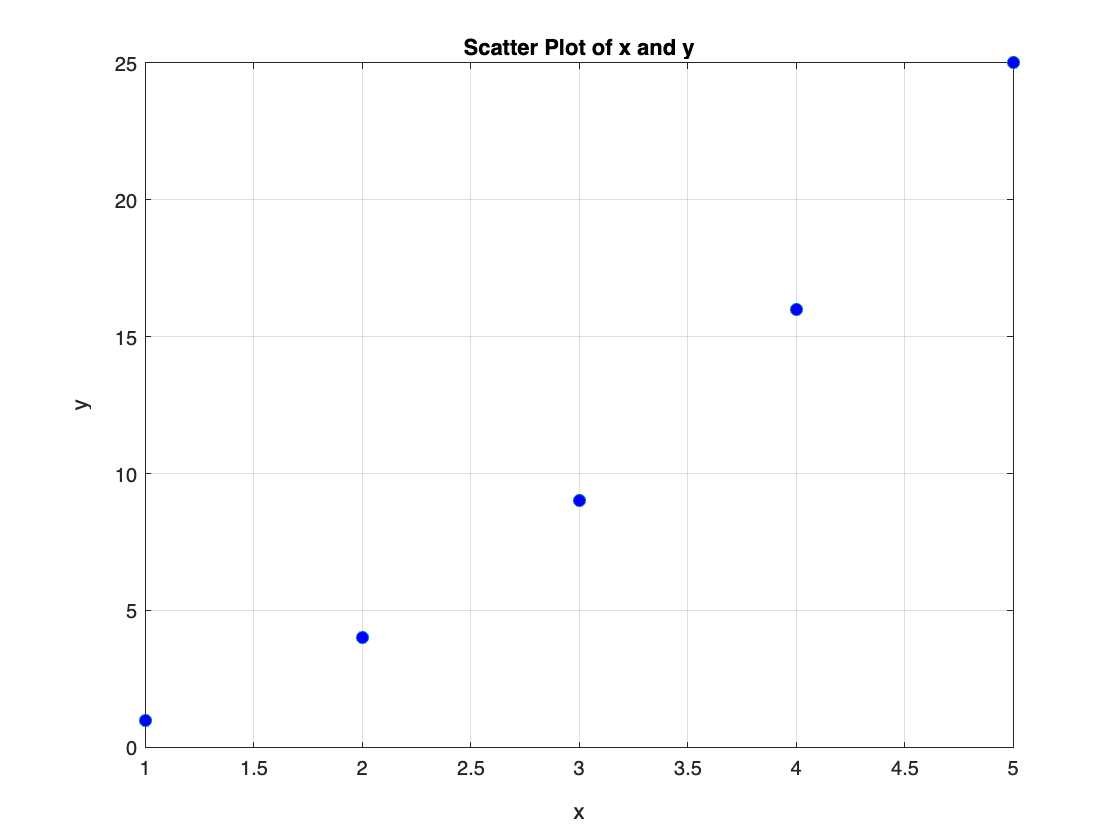

% Create data
x = 1:5;
y = x.^2;

% Plot points
plot(x, y, 'o', 'MarkerFaceColor', 'blue');

% Add labels and title
xlabel('x');
ylabel('y');
title('Scatter Plot of x and y');

% Show the plot
grid on;

Plot a curve with the expression

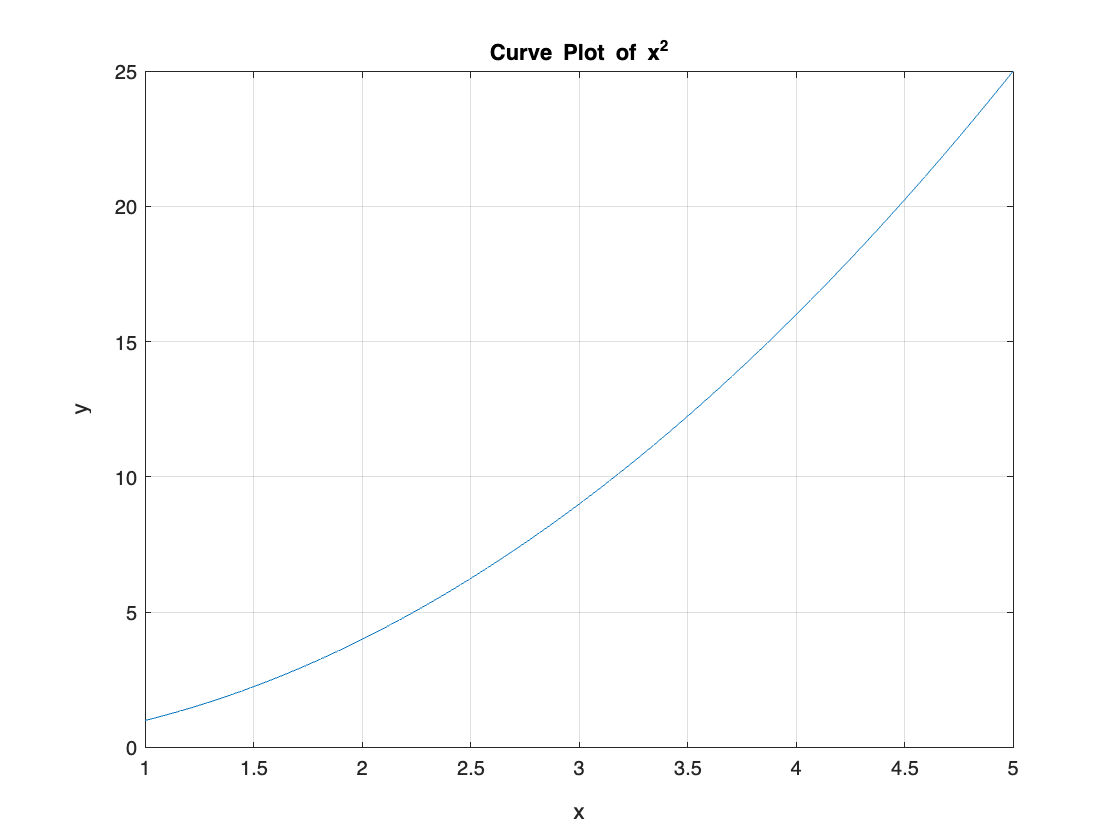

% Create data
x = linspace(1, 5, 100);
y = x.^2;

% Plot the curve
plot(x, y);

% Add labels and title
xlabel('x');
ylabel('y');
title('Curve Plot of x^2');

% Show the plot
grid on;

Scatter plot

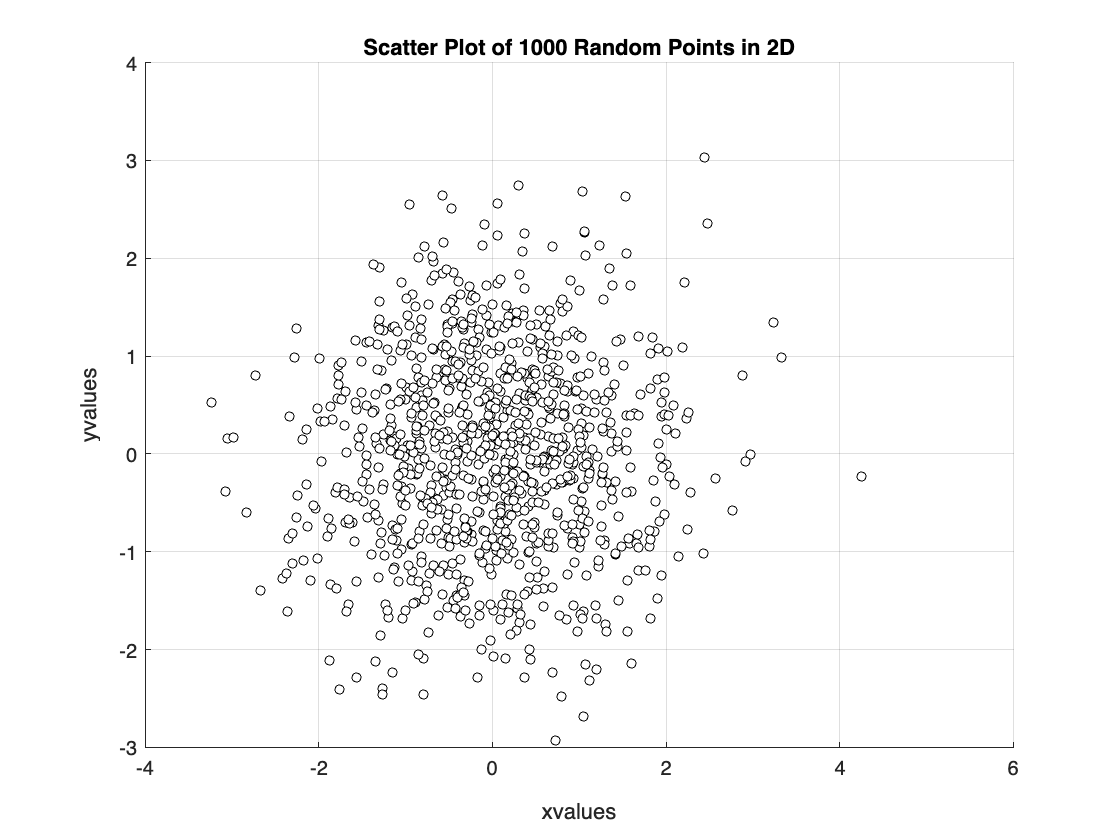

rng(42);  % Setting seed for reproducibility

% Generate 1000 random points in 2D
y = table(randn(1000, 1), randn(1000, 1), 'VariableNames', {'xvalues', 'yvalues'});

% Scatter plot using MATLAB
scatter(y.xvalues, y.yvalues, 20, 'MarkerFaceColor', 'white', 'MarkerEdgeColor', 'black', 'LineWidth', 0.5);
xlabel('xvalues');
ylabel('yvalues');
title('Scatter Plot of 1000 Random Points in 2D');
grid on;

Density map

nbins=[10 10];
[N,C]=hist3([y.xvalues, y.yvalues],nbins)

N =      0     0     1     1     1     3     1     0     0     0
     1     1     6    11     6    10     6     1     0     0
     2     4    12    20    30    29    16    10     2     0
     1     4    30    37    43    52    40    28     8     3
     0    11    18    48    59    70    43    26     5     2
     3     5    17    28    47    40    30    11     5     1
     0     4     7    17    17    22    13     3     2     1
     0     0     0     3     5     5     2     1     1     1
     0     0     0     1     2     0     2     1     0     0
     0     0     0     0     1     0     0     0     0     0


C = 1×2 cell array
    {[-2.8592 -2.1105 -1.3618 -0.6132 0.1355 0.8842 1.6328 2.3815 3.1302 3.8788]}    {[-2.6264 -2.0310 -1.4355 -0.8401 -0.2447 0.3507 0.9462 1.5416 2.1370 2.7324]}


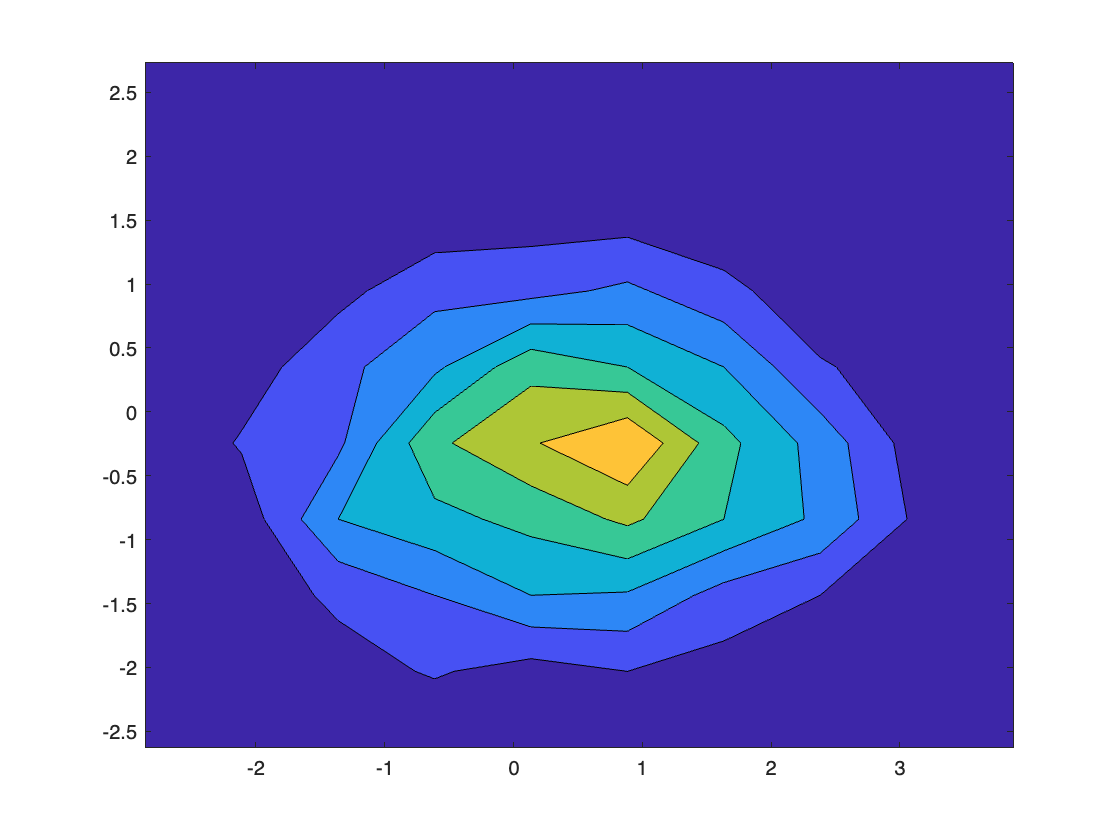

contourf(C{1},C{2},N)

### Variable-length input argument list to a function

Functions func_main, func_main2, func1, and func2 are defined at the end of this document.

% normal arguments
result = func_main(1, 2.4, 0.6);
disp(result);

     4



% Variable-length input argument list, case 1
result2 = func_main2(1, @func1,2.4,0.6);

d: 2.40
e: 0.60


disp(result2);

     4



% Variable-length input argument list, case 2
result3 = func_main2(1, @func2, 10, 20, 1, -3);
disp(result3);

    28



### Pass name-value arguments to a function

% name-value arguments
result4 = func_main3(a=1,b=2.4,c=0.6);
disp(result4);

     4




% name-value arguments, with defaults
result5 = func_main4(a=1,b=2.4);
disp(result5);

    3.4000



### Define MATLAB functions

1. myfunction

function b = myfunction(x)
    % a simple function to perform x square
    b = x * x;
end

 2. func_main (normal arguments)

% A function with normal arguments
function result = func_main(a, b, c)
    result = a + b + c;
end

 3. func_main2 (name-value arguments)

% A function with name-value arguments
function result = func_main2(a, func_2nd, varargin)
% a: first argument; func_2nd: 2nd function; 
% varargin: arguments passing to func_2nd.
    result = a + func_2nd(varargin{:});
end

 4. func1

% Usage case 1
function result =  func1(d, e)
    fprintf('d: %.2f\n', d);
    fprintf('e: %.2f\n', e);
    result = d + e;
end

5. func2

% Usage case 2
function result = func2(f, g, h, i)
    result = f+g+h*i;
end

6. func_main3 (name-value arguments)

% A function with name-value arguments
function result = func_main3(NameValueArgs)
arguments
    NameValueArgs.a
    NameValueArgs.b
    NameValueArgs.c
end
result = NameValueArgs.a + NameValueArgs.b + NameValueArgs.c;
end

7. func_main4 (name-value arguments, with defaults)

% A function with name-value arguments (with default values)
function result = func_main4(NameValueArgs)
arguments
    NameValueArgs.a = 0
    NameValueArgs.b = 0
    NameValueArgs.c = 0
end
result = NameValueArgs.a + NameValueArgs.b + NameValueArgs.c;
end